# 実践ロバスト制御　第4章演習問題

clear; close all; clc;

## 問題1

**公式**$\|MN\|_\infty\le\|M\|_\infty \|N\|_\infty$**を使って、**$\|G\|_\infty<1$**かつ**$\|H\|_\infty<1$**の十分条件は**


$$\left\|
\pmatrix{G\cr H}
\right\|_\infty
<1$$


**となることを示せ。**

仮に$\|G\|_\infty\le\|H\|_\infty$とおくと、


$$\|H\|_\infty=
\left\|
\pmatrix{O & I}
\pmatrix{G\cr H}
\right\|_\infty
\le
\left\|
\pmatrix{O & I}
\right\|_\infty
\left\|
\pmatrix{G \cr H}
\right\|_\infty=
\left\|
\pmatrix{G \cr H}
\right\|_\infty$$


が成り立つことから、


$$\|G\|_\infty\le\|H\|_\infty\le
\left\|
\pmatrix{G\cr H}
\right\|_\infty$$


上式が導ける。従って、以上より十分条件であることが示される。

## 問題2

**直結フィードバック制御系において、制御対象**$P$**と制御器**$K$**はともに1次システムとし、それらの状態空間実現が次式で与えられるとき、つぎの各問いに答えよ。**


$$P=(a_p,b_p,1,0),K=(a_k,b_k,1,d_k)$$


**ただし、**$b_p$**、**$b_k$**、**$d_k$**は非零とする。**

**1. **$r$**から**$y$**までの状態空間実現**$G_{cl}=(A_{cl},B_{cl},C_{cl},D_{cl})$**を求めよ。**

状態変数を$\pmatrix{x_P&x_K}^\top$とすると、


$$A_{cl}=\pmatrix{a_p-b_pd_k & b_p\cr -b_k& a_k}\text{、}
B_{cl}=\pmatrix{b_pd_k\cr b_k}\text{、}
C_{cl}=\pmatrix{c_p &0}\text{、}
D_{cl}=0$$


(ref: T. Chen, B. Francis, Optimal Sampled-Data Control Systems, p.96)

**2. **$P$**の極が制御器**$K$**の零点で極零相殺されるとき、**$P$**の極が**$A_{cl}$**の固有値になることを示せ。**


$$P=\frac{b_p}{s-a_p}\text{、}
K=\frac{b_k}{s-a_k}+d_k$$


であることから、極零相殺がおこるのは、$a_p=a_k-b_k/d_k$のとき。

愚直に$A_{cl}$の固有値を計算して$a_p=a_k-b_k/d_k$を用いることで$P$の極が$A_{cl}$の固有値になることを示すことができる。

**3. 上記2.のもとで、**$P$**の極が**$(A_{cl},B_{cl})$**の不可制御モードになることを示せ。**


$$\mathrm{rank}\lbrace\pmatrix{A_{cl}-a_pI&B_cl}\rbrace=1<2$$


より不可制御モードである。

## 問題3

**加法的摂動に対する、ロバスト安定化と感度関数の周波数整形を同時に考えた混合感度問題は**


$$\left\|
\pmatrix{\frac{1}{1+PK}W_S\cr \frac{K}{1+PK}W_T}
\right\|_\infty
<1$$


**を満たす内部安定化制御器**$K$**を求める問題となる。ただし、**$P$**は1入出力系とし、**$W_S$**および**$W_T$**は重み関数である。このとき、つぎの各問いに答えよ。**

**1. 一般化プラント**$G$**のブロック線図を描き、**$G$**の伝達行列表現を求めよ。**

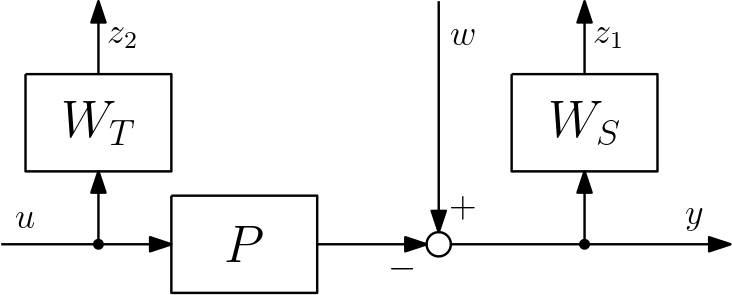

ブロック線図より、


$$G=\pmatrix{
W_S&-W_TP\cr
0&W_T\cr
1&-P
}$$


**2. 上記1.の一般化プラントは標準**$H_\infty$**制御問題の仮定A1～A4を満たすかどうか考察せよ。**

**仮定A1**:$(A,B_2)$は可安定、かつ、$(C_2,A)$は可検出（*実際の制御対象が可安定、可検出であることに加えて、重み関数が全て安定）

両方とも〇。$P$に加え$W$も安定。

**仮定A2**:$D_{12}$は縦長列フルランク、かつ、$D_{21}$は横長行フルランク

$D_{12}$は〇。$u$から$z_2$への直達項があるため。

$D_{21}$は〇。$w$から$y$の直達項が$1$であるため。

**仮定A3**:$G_{12}$は虚軸上に不変零点を持たない。

**仮定A4**:$G_{21}$は虚軸上に不変零点を持たない。

両方とも1.の$G$から〇。（$W_S$および$W_T$が安定で、$W_T$が直達項を持ち、$P$が虚軸上に極を持たない想定）

**3. **$W_S=W_T=1$**としたとき、一般化プラント**$G$**の状態空間実現を求めよ。ただし、**$P=(A_p,B_p,C_p,0)$**とする。**

1.の図より、


$$\dot{x}_p=A_px_p+B_pu\\
z_1 = -C_px_p+w\\
z_2 = u\\
y = -C_px_p+w$$


であるため、


$$G=
\left(
\begin{array}{c|cc}
A_p&0&B_p\\
\hline
-C_p&1&0\\
0&0&1\\
-C_p&1&0
\end{array}
\right)$$
